% matlab 实现suite2p功能
% read tiff
frames = tiff_read("C:\Users\Achuan-2\Desktop\test\file_00001.tif");
ops = register.suite2p.default_ops();
frames = uint16(frames);
% 获取refimg

tic
refImg = register.suite2p.compute_reference(frames,ops);
toc

Elapsed time is 2.486716 seconds.


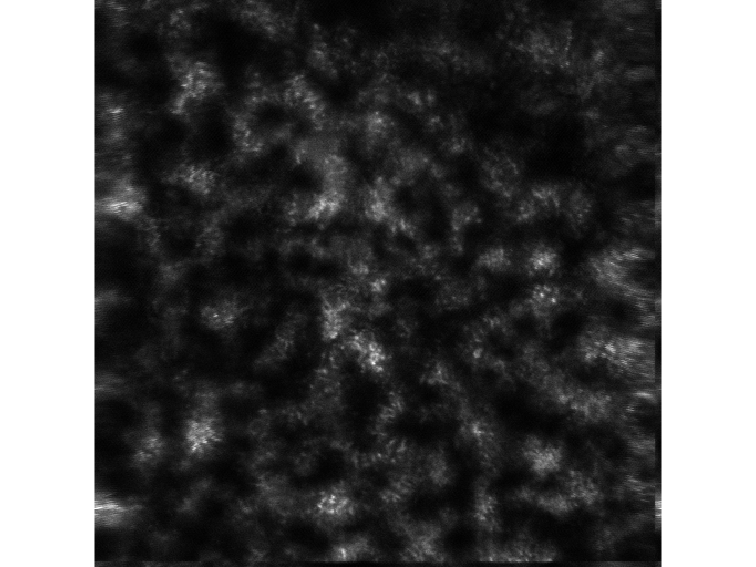

figure;
imshow(refImg,[]);

% 进行配准
tic
refAndMasks = register.suite2p.compute_reference_masks(refImg, ops);
[frames, ymax, xmax, cmax] = register.suite2p.register_frames(refAndMasks, frames,  ops);
toc

Elapsed time is 1.280002 seconds.


tiff_save(frames,'reg2.tif');
